v_air  = out.logsout.get("v_AirspeedSensor").Values.Data;
v_real = out.logsout.get("v").Values.Data;
a_acc  = out.logsout.get("a_Acc").Values.Data;

t  = out.logsout.get("v").Values.Time;
dt = mean(diff(t));

R = var(v_air - v_real);   % airspeed error

Qv = 0.1;      % speed process noise
Qb = 0.001;    % bias drift noise

x = [v_air(1); 0];         % [speed; accel_bias]
P = diag([100, 1]);

v_est = zeros(size(v_real));
b_est = zeros(size(v_real));

for k = 2:length(v_real)

    % State prediction
    A = [1, -dt;
         0,  1];

    B = [dt;
         0];

    Q = diag([Qv, Qb]);

    x_pred = A*x + B*a_acc(k);
    P_pred = A*P*A' + Q;

    % Airspeed measurement update
    H = [1, 0];

    innovation = v_air(k) - H*x_pred;

    % optional: ignore bad airspeed spikes
    if abs(innovation) > 30
        R_use = 100*R;
    else
        R_use = R;
    end

    K = P_pred*H'/(H*P_pred*H' + R_use);

    x = x_pred + K*innovation;
    P = (eye(2) - K*H)*P_pred;

    v_est(k) = x(1);
    b_est(k) = x(2);

end

rmse_air = sqrt(mean((v_air-v_real).^2));
rmse_kal = sqrt(mean((v_est-v_real).^2));

fprintf("Airspeed RMSE = %.3f m/s\n", rmse_air);

Airspeed RMSE = 23.694 m/s


fprintf("Kalman RMSE   = %.3f m/s\n", rmse_kal);

Kalman RMSE   = 23.691 m/s


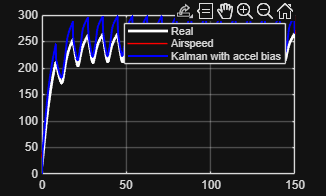


figure
plot(t,v_real,'w','LineWidth',2)
hold on
plot(t,v_air,'r')
plot(t,v_est,'b','LineWidth',1.5)
legend("Real","Airspeed","Kalman with accel bias")
grid on